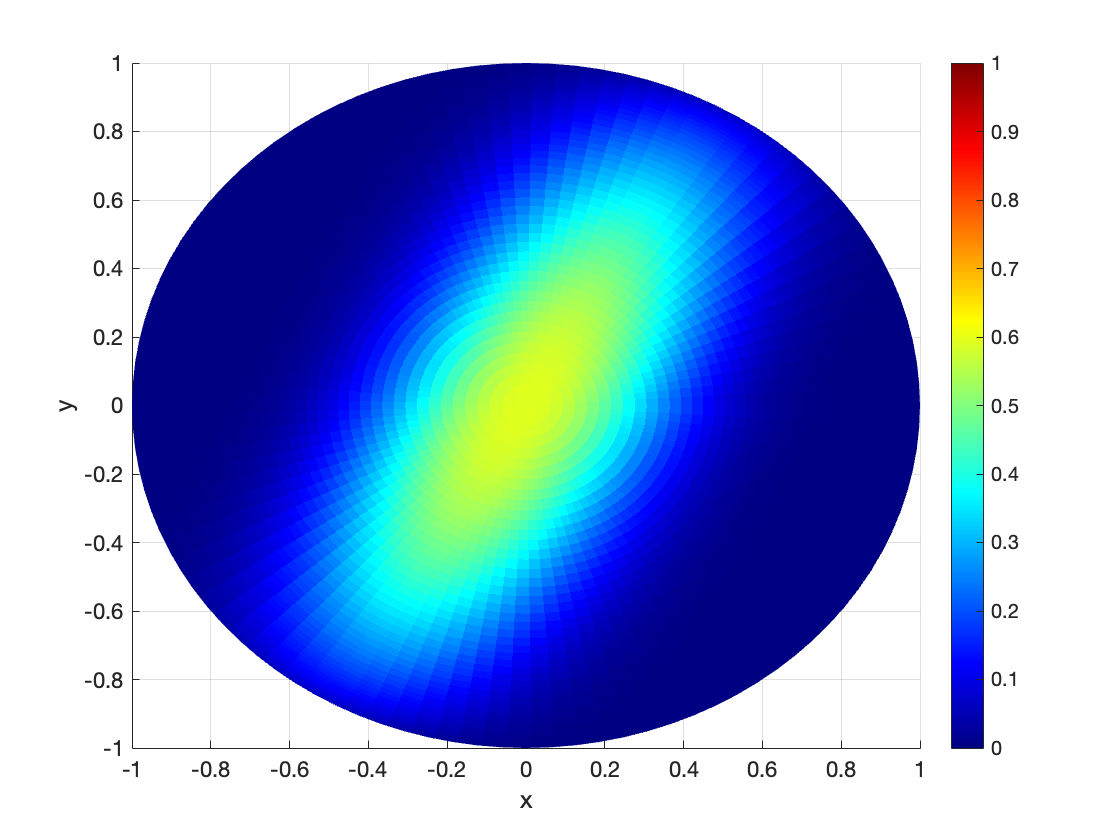

clear all;


dim=20;
state=zeros(dim,1);
state(1)=1;

sigmax=spinOp((dim-1)/2,'x');
sigmay=spinOp((dim-1)/2,'y');
sigmaz=spinOp((dim-1)/2,'z');

squeezing_time=3;

state_unsqueezed=state;
state=expm(-1i*(sigmax^2)*squeezing_time)*state;
state_squeezed=expm(-1i*sigmaz*squeezing_time)*state;

rho=state_squeezed*state_squeezed';
husimi_plot(rho,100,100);


uncertainty_unsqueezed=state_unsqueezed'*sigmax^2*state_unsqueezed-(state_unsqueezed'*sigmax*state_unsqueezed)^2;
uncertainty_squeezed=state_squeezed'*sigmax^2*state_squeezed-(state_squeezed'*sigmax*state_squeezed)^2;


uncertainty_unsqueezed=state_unsqueezed'*sigmay^2*state_unsqueezed-(state_unsqueezed'*sigmay*state_unsqueezed)^2;
uncertainty_squeezed=real(state_squeezed'*sigmay^2*state_squeezed-(state_squeezed'*sigmay*state_squeezed)^2);




10^(uncertainty_squeezed/uncertainty_unsqueezed/10)

ans = 3.0217

function husimi_plot(rho,theta_num,phi_num)
    theta_list=[0:pi/theta_num:pi];
    phi_list=[0:2*pi/phi_num:2*pi];
    for i=1:length(theta_list)
        theta=theta_list(i);
        for j=1:length(phi_list)
            phi=phi_list(j);
            result(i,j)=husimi_Q(rho,theta,phi);
        end
    end
    
    f1=figure;
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,abs(result'));
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);
    clim([0 1]);
    xlabel('x');
    ylabel('y');
    view([0 90]);
    set(f1,"Visible","On");
    set(surf,"LineStyle","none", "FaceColor","texturemap",...
        "FaceLighting","gouraud");
    colorbar;colormap jet
end

function output=husimi_Q(rho,theta,phi)
    dim=size(rho,1);
    output=coherent_state(dim,theta,phi)'*rho*coherent_state(dim,theta,phi);
end

function output=coherent_state(dim,theta,phi)
    sigmay=spinOp((dim-1)/2,'y');
    sigmaz=spinOp((dim-1)/2,'z');
    initial_state=zeros(dim,1);
    initial_state(1)=1;
    yrotation=expm(-1i*sigmay*theta)*initial_state;
    zrotation=expm(-1i*sigmaz*phi)*yrotation;
    output=zrotation;
end